% Pattern to match the files (adjust folder path if necessary)
filePattern = 'res_C*_p8000_rep*.mat';
files = dir(filePattern);

% Use a Map to group data by 'C' value
% Key: C value (string), Value: Matrix of accumulated vectors
dataGroups = containers.Map;

fprintf('Found %d files. Processing...\n', length(files));

Found 80 files. Processing...



for k = 1:length(files)
    baseFileName = files(k).name;
    fullFileName = fullfile(files(k).folder, baseFileName);
    
    % 1. Parse "C" value from filename using Regular Expression
    % Looks for pattern "C" followed by digits/dots, before an underscore
    tokens = regexp(baseFileName, 'res_C([\d\.]+)_', 'tokens');
    
    if isempty(tokens)
        fprintf('Skipping file with unexpected name format: %s\n', baseFileName);
        continue;
    end
    
    cValStr = tokens{1}{1}; % Extracted C value as a string (e.g., '0.2')
    
    % 2. Load the specific variable from the .mat file
    if isfile(fullFileName)
        data = load(fullFileName, 'pi_final');
        
        if isfield(data, 'pi_final')
            % 3. Grab first 10 elements
            vec10 = data.pi_final(1:10);
            
            % Ensure it is a column vector (10x1)
            vec10 = vec10(:); 
            
            % 4. Store in the Map group
            if isKey(dataGroups, cValStr)
                % Append as a new column
                dataGroups(cValStr) = [dataGroups(cValStr), vec10];
            else
                % Initialize with the first vector
                dataGroups(cValStr) = vec10;
            end
        else
            fprintf('Variable pi_final not found in %s\n', baseFileName);
        end
    end
end

% 5. Compute and Display Statistics for each Group
keys = dataGroups.keys;

fprintf('\n%-10s | %-15s | %-15s\n', 'C Value', 'Files Processed', 'Stat Check');

C Value    | Files Processed | Stat Check     


fprintf('%s\n', repmat('-', 1, 50));

--------------------------------------------------



for k = 1:length(keys)
    cVal = keys{k};
    groupData = dataGroups(cVal); % This is a 10 x N matrix (N = files per group)
    
    numFiles = size(groupData, 2);
    
    % Compute Mean across the 2nd dimension (across files)
    meanVec = mean(groupData, 2);
    
    % Compute Variance across the 2nd dimension
    varVec = var(groupData, 0, 2); 
    
    % Display Summary
    fprintf('%-10s | %-15d | Mean/Var Calculated\n', cVal, numFiles);
    
    % Display detailed results for this C value
    fprintf('  -> Results for C=%s (Vectors of size 10):\n', cVal);
    disp(table(meanVec, varVec, 'VariableNames', {'Mean', 'Variance'}));
    fprintf('\n');
end

0.2        | 20              | Mean/Var Calculated


  -> Results for C=0.2 (Vectors of size 10):


     Mean      Variance
    _______    ________

    0.80868    0.078599
    0.83534    0.049858
    0.80815    0.078079
    0.81088    0.054975
    0.83725    0.059428
    0.88514     0.04418
    0.87612    0.046776
     0.8586    0.052262
    0.75212    0.096095
    0.73415    0.097429



0.4        | 20              | Mean/Var Calculated


  -> Results for C=0.4 (Vectors of size 10):


     Mean      Variance
    _______    ________

    0.70874    0.14944 
    0.74895    0.14478 
    0.77645    0.11403 
    0.74757    0.14369 
    0.76583    0.13261 
     0.7432    0.15324 
    0.79574    0.12574 
    0.71245    0.15019 
    0.75479    0.13824 
    0.71085    0.16008 



0.6        | 20              | Mean/Var Calculated


  -> Results for C=0.6 (Vectors of size 10):


     Mean      Variance
    _______    ________

    0.14393    0.023101
    0.26681     0.11399
    0.27354     0.11646
    0.16841    0.046511
    0.27961     0.13385
    0.23081     0.10955
    0.30753     0.11754
    0.22905    0.095393
    0.15615    0.026451
    0.19319    0.072873



0.8        | 20              | Mean/Var Calculated


  -> Results for C=0.8 (Vectors of size 10):


     Mean      Variance
    _______    ________

    0.10896    0.043308
    0.33335     0.18357
    0.24602     0.14397
      0.128    0.049411
    0.25314     0.12719
    0.16045    0.077291
    0.33177     0.17574
    0.23118      0.1018
    0.14067    0.062044
    0.32587     0.18195



clc; clear; close all;

% 1. Setup
filePattern = 'res_C*_p8000_rep*.mat';
files = dir(filePattern);

% Initialize a struct array to hold the data
% We will store C value and the vector for each file
dataList = struct('C', {}, 'vec', {});
count = 0;

fprintf('Found %d files. Loading data...\n', length(files));

Found 80 files. Loading data...



% 2. Load Data into Structure
for k = 1:length(files)
    baseFileName = files(k).name;
    fullFileName = fullfile(files(k).folder, baseFileName);
    
    % Parse "C" value using Regex
    tokens = regexp(baseFileName, 'res_C([\d\.]+)_', 'tokens');
    
    if ~isempty(tokens)
        cVal = str2double(tokens{1}{1});
        
        if isfile(fullFileName)
            loaded = load(fullFileName, 'pi_final');
            
            if isfield(loaded, 'pi_final')
                % Grab first 10 elements
                vec = loaded.pi_final(1:10);
                vec = vec(:); % Ensure column vector
                
                % Store in our list
                count = count + 1;
                dataList(count).C = cVal;
                dataList(count).vec = vec;
            end
        end
    end
end

if count == 0
    error('No valid data found. Check file paths and names.');
end

% 3. Group by C and Calculate Statistics
% Get all unique C values found
allCVals = [dataList.C];
uniqueCs = unique(allCVals);

fprintf('\nProcessing %d unique C values...\n', length(uniqueCs));


Processing 4 unique C values...


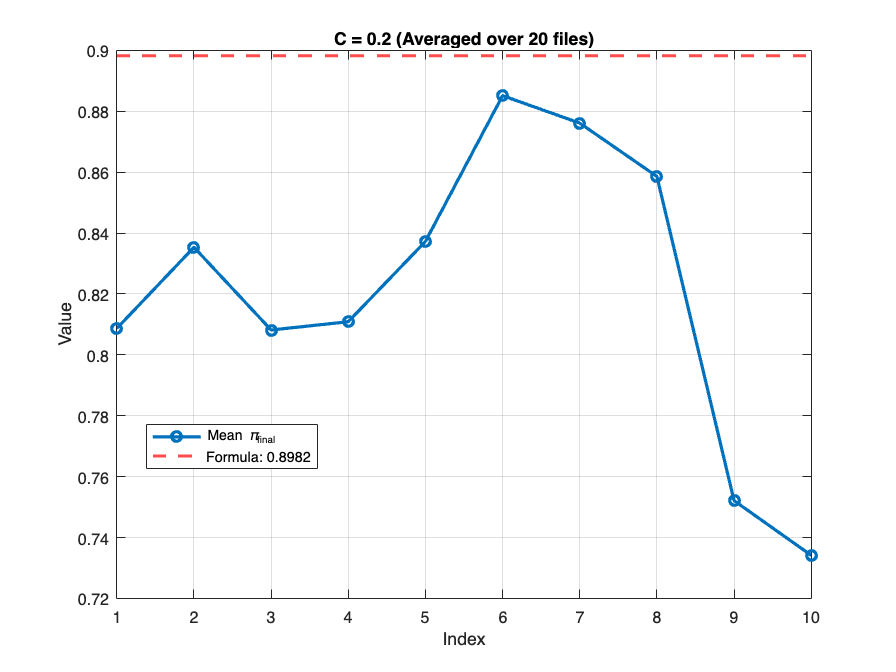

C=0.2   | Files: 20  | Formula Val: 0.8982 | Mean[1]: 0.8087


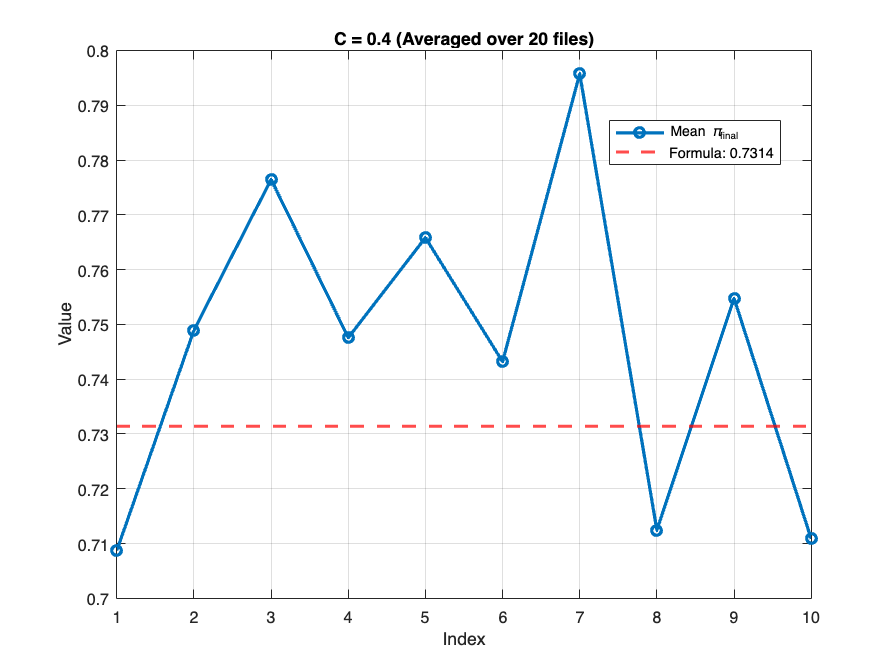

C=0.4   | Files: 20  | Formula Val: 0.7314 | Mean[1]: 0.7087


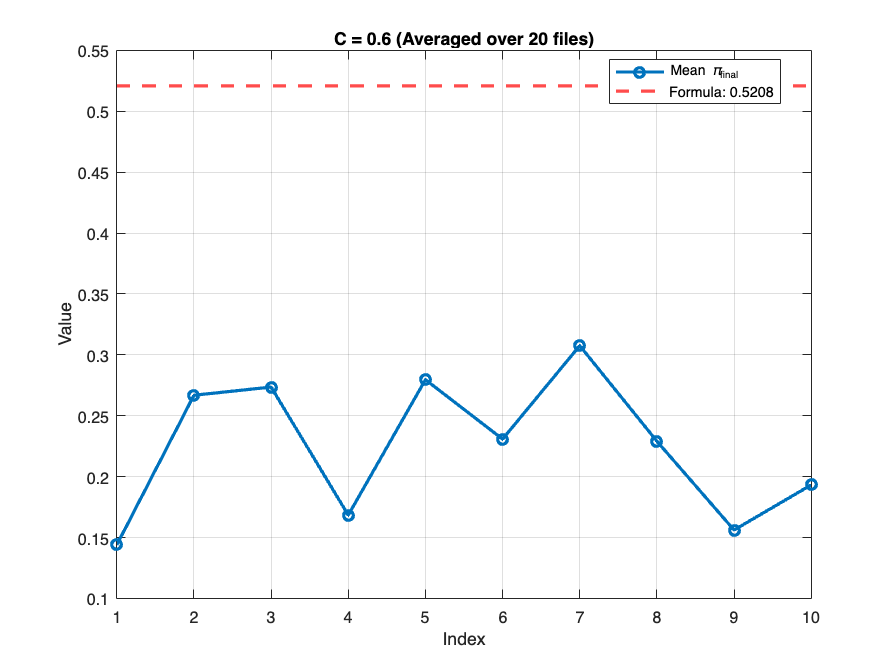

C=0.6   | Files: 20  | Formula Val: 0.5208 | Mean[1]: 0.1439


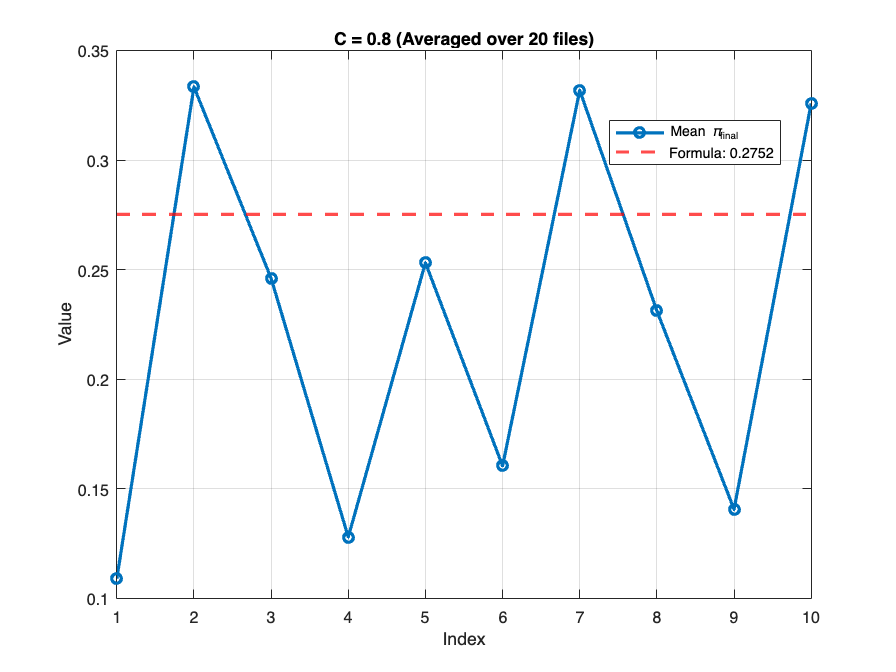

C=0.8   | Files: 20  | Formula Val: 0.2752 | Mean[1]: 0.1090



for i = 1:length(uniqueCs)
    thisC = uniqueCs(i);
    
    % Find all entries matching this C
    matchIdx = (allCVals == thisC);
    
    % Concatenate vectors into a matrix (Rows=10, Cols=NumFiles)
    groupVectors = [dataList(matchIdx).vec];
    numFiles = size(groupVectors, 2);
    
    % --- Calculation ---
    
    % 1. Mean Vector (averaging across files)
    meanVec = mean(groupVectors, 2);
    
    % 2. Theoretical Formula Value
    % Formula: ln(1/C) / ln((C+1)/C)
    val_numerator = log(1/thisC);
    val_denominator = log((thisC + 1)/thisC);
    formulaVal = val_numerator / val_denominator;
    
    % --- Plotting ---
    figure;
    plot(1:10, meanVec, '-o', 'LineWidth', 2, 'DisplayName', 'Mean \pi_{final}');
    hold on;
    
    % Add horizontal line for the formula value
    yline(formulaVal, '--r', 'LineWidth', 2, ...
        'DisplayName', sprintf('Formula: %.4f', formulaVal));
    
    hold off;
    grid on;
    title(sprintf('C = %g (Averaged over %d files)', thisC, numFiles));
    xlabel('Index');
    ylabel('Value');
    legend('Location', 'Best');
    
    % Display text result
    fprintf('C=%-5g | Files: %-3d | Formula Val: %.4f | Mean[1]: %.4f\n', ...
        thisC, numFiles, formulaVal, meanVec(1));
end

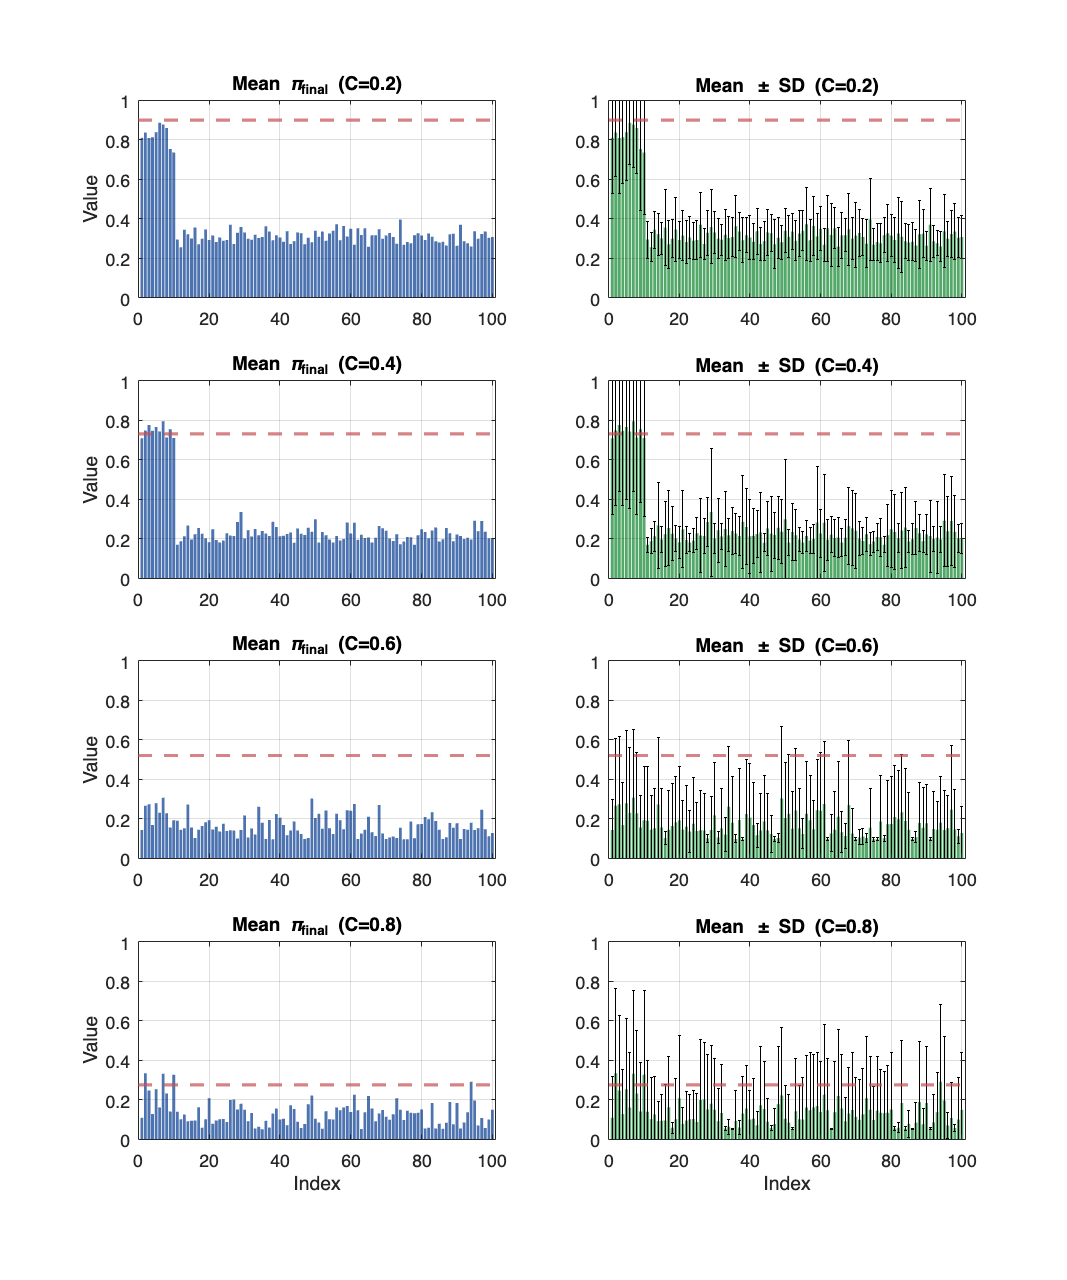

clc; clear; close all;

% --- 1. Settings ---
figWidth = 1000;
figHeight = 1200;
barColorLeft = [0.3 0.45 0.69];   % Muted Blue
barColorRight = [0.33 0.66 0.41]; % Muted Green
lineColor = [0.77 0.31 0.32];     % Muted Red
fontName = 'Helvetica';           % Or 'Arial'
fontSize = 11;

% --- 2. Load Data ---
filePattern = 'res_C*_p8000_rep*.mat';
files = dir(filePattern);
dataList = struct('C', {}, 'vec', {});
count = 0;

for k = 1:length(files)
    baseFileName = files(k).name;
    fullFileName = fullfile(files(k).folder, baseFileName);
    
    tokens = regexp(baseFileName, 'res_C([\d\.]+)_', 'tokens');
    if ~isempty(tokens)
        cVal = str2double(tokens{1}{1});
        if isfile(fullFileName)
            loaded = load(fullFileName, 'pi_final');
            if isfield(loaded, 'pi_final')
                vec = loaded.pi_final(1:100); 
                vec = vec(:); 
                count = count + 1;
                dataList(count).C = cVal;
                dataList(count).vec = vec;
            end
        end
    end
end

if count == 0, error('No valid data found.'); end

% --- 3. Process & Plot ---
allCVals = [dataList.C];
uniqueCs = unique(allCVals);
numCs = length(uniqueCs);

% Limit to 4 rows
if numCs > 4
    uniqueCs = uniqueCs(1:4);
    numCs = 4; 
end

figure('Position', [100, 100, figWidth, figHeight], 'Color', 'w');

for row = 1:4
    if row <= numCs
        thisC = uniqueCs(row);
        
        % Data Calculation
        matchIdx = (allCVals == thisC);
        groupVectors = [dataList(matchIdx).vec];
        meanVec = mean(groupVectors, 2);
        stdVec = std(groupVectors, 0, 2);
        formulaVal = log(1/thisC) / log((thisC + 1)/thisC);
        indices = 1:100;
        
        % --- Left Column: Mean Bar Plot ---
        ax1 = subplot(4, 2, (row-1)*2 + 1);
        bar(indices, meanVec, 'FaceColor', barColorLeft, 'EdgeColor', 'none');
        hold on;
        yline(formulaVal, '--', 'Color', lineColor, 'LineWidth', 2);
        hold off;
        
        % Styling
        ylim([0 1]);
        xlim([0 101]);
        grid on;
        set(gca, 'FontName', fontName, 'FontSize', fontSize, 'Layer', 'top');
        title(sprintf('Mean \\pi_{final} (C=%g)', thisC), 'FontWeight', 'bold');
        if row == 4, xlabel('Index'); end
        ylabel('Value');
        
        % --- Right Column: Mean + Error Bar ---
        ax2 = subplot(4, 2, (row-1)*2 + 2);
        b = bar(indices, meanVec, 'FaceColor', barColorRight, 'EdgeColor', 'none');
        hold on;
        % Error bars
        er = errorbar(indices, meanVec, stdVec, 'k', 'LineStyle', 'none');
        er.CapSize = 2;
        yline(formulaVal, '--', 'Color', lineColor, 'LineWidth', 2);
        hold off;
        
        % Styling
        ylim([0 1]);
        xlim([0 101]);
        grid on;
        set(gca, 'FontName', fontName, 'FontSize', fontSize, 'Layer', 'top');
        title(sprintf('Mean \\pm SD (C=%g)', thisC), 'FontWeight', 'bold');
        if row == 4, xlabel('Index'); end
        % ylabel('Value');
    else
        % Empty Placeholders
        subplot(4, 2, (row-1)*2 + 1); axis off;
        subplot(4, 2, (row-1)*2 + 2); axis off;
    end
end